# Bayesian Optimization of Combinatorial Structures

Copyright (C) 2018 R. Baptista & M. Poloczek

Copyright (C) 2018 MIT & University of Arizona

Authors: Ricardo Baptista & Matthias Poloczek

E-mails: rsb@mit.edu & poloczek@email.arizona.edu

% BOCS is free software: you can redistribute it and/or modify
% it under the terms of the GNU General Public License as published by
% the Free Software Foundation, either version 3 of the License, or
% (at your option) any later version.
%
% BOCS is distributed in the hope that it will be useful,
% but WITHOUT ANY WARRANTY; without even the implied warranty of
% MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the
% GNU General Public License for more details.
%
% You should have received a copy of the GNU General Public License 
% along with BOCS.  If not, see <http://www.gnu.org/licenses/>.

## Add Paths

clear; close all; clc

addpath(genpath('../algorithms'))
addpath(genpath('../stat_model'))
addpath(genpath('../test_problems/IsingModel'))
addpath(genpath('../tools'))

## Begin Code Example

% Save inputs in struct
inputs = struct;
inputs.n_vars     = 12;
inputs.evalBudget = 100;
inputs.n_init     = 20;
inputs.lambda     = 1e-4;
inputs.estimator  = 'horseshoe';

% Generate random 3x3 graphical model
Theta   = rand_ising_grid(9);
Moments = ising_model_moments(Theta);

% Save objective function and regularization term
inputs.model    = @(x) KL_divergence_ising(Theta, Moments, x);
inputs.penalty  = @(x) inputs.lambda*sum(x,2);

% Generate initial samples for statistical models
inputs.x_vals   = sample_models(inputs.n_init, inputs.n_vars);
inputs.y_vals   = inputs.model(inputs.x_vals);

% Run BOCS-SDP and BOCS-SA (order 2)
B_SA  = BOCS(inputs.model, inputs.penalty, inputs, 2, 'SA');
B_SDP = BOCS(inputs.model, inputs.penalty, inputs, 2, 'sdp');

## Plot results

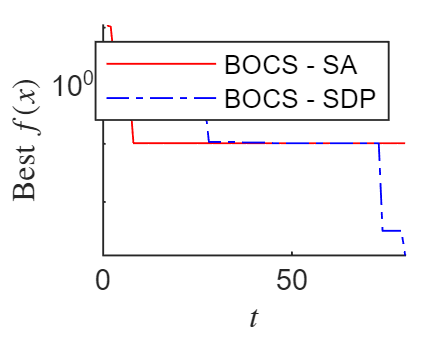

figure
hold on
plot(1:length(B_SA.objVals),  cummin(B_SA.objVals), '-r');
plot(1:length(B_SDP.objVals), cummin(B_SDP.objVals), '-.b');
set(gca,'YScale','log')
xlabel('$t$','interpreter','latex')
ylabel('Best $f(x)$','interpreter','latex')
legend({'BOCS - SA','BOCS - SDP'},'location','northeast')
hold off